# Taller 2

Juan Pablo Gaviria Salazar

## Punto 7

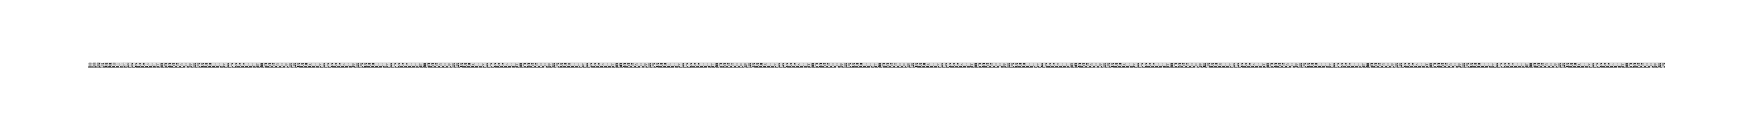

imagen = imread("Data/imagenPersonal.jpg");
imagenGris = rgb2gray(imagen);
imagenGris = im2double(imagenGris);
[U,S,V] = svd(imagenGris);
singVal = sort(diag(S),'descend');

[k,m] = size(imagenGris);

n = size(singVal,1);
A = zeros(k,m);
serieImagenes = zeros(k,m,n);
for i=1:n
    A = A + singVal(i)*U(:,i)*V(:,i)';
    serieImagenes(:,:,i) = A;
end

montage(serieImagenes(:,:,1:50));

## Punto 13

% Se carga la informacion
data = readmatrix("Data/100_Portfolios_ME_INV_10x10_tratado.txt");
data(:,1) = [];
iteraciones = 10;

% Se eliminan los datos raros a traves del metodo de maxima curtosis
idx = kur_main(data);
B = data(idx==0, :);

% Definicion de la matriz A
A = B*B';

% Definicion del vector solucion
n = size(A,1);
x = zeros(n, iteraciones);
b = zeros(n, iteraciones);
xcalc1 = zeros(n, iteraciones);
error1 = zeros(iteraciones,1);
xcalc2 = zeros(n, iteraciones);
error2 = zeros(iteraciones,1);
xcalc3 = zeros(n, iteraciones);
error3 = zeros(iteraciones,1);
xcalc4 = zeros(n, iteraciones);
error4 = zeros(iteraciones,1);
xcalc5 = zeros(n, iteraciones);
error5 = zeros(iteraciones,1);
xcalc6 = zeros(n, iteraciones);
error6 = zeros(iteraciones,1);

for i=1:10
    x(:,i) = 0.05*i*randn(n,1);
    
    % Se halla b
    b(:,i) = A*x(:,i);
    
    %%% 1 solucion: Inversa
    xcalc1(:,i) = inv(A)*b(:,i);
    error1(i) = norm(abs(x(:,i)-xcalc1(:,i)), 2);
    
    %%% 2 solucion: Inversa generalizada
    invGenA = A\eye(n);
    xcalc2(:,i) = invGenA*b(:,i);
    error2(i) = norm(abs(x(:,i)-xcalc2(:,i)), 2);
    
    %%% 3 solucion: Descomposicion LU
    [l, u] = lu(A);
    y = inv(l)*b(:,i);
    xcalc3(:,i) = inv(u)*y;
    error3(i) = norm(abs(x(:,i)-xcalc3(:,i)), 2);
    
    %%% 4 solucion: Cholesky
    % Debido a que la matriz esta muy mal condicionada, matlab saca error de
    % que la matriz no esta definida positivamente. Se implementa Cholesky
    % manual para calcular x
    % Jan Motl (2020). Cholesky decomposition (https://www.mathworks.com/matlabcentral/fileexchange/71304-cholesky-decomposition), MATLAB Central File Exchange. Retrieved April 17, 2020.
    l = A;
    for h=1:n
        l(h:n, h) = l(h:n, h) - l(h:n, 1:h-1) * l(h, 1:h-1)';
        l(h, h) = sqrt(l(h, h));
        l(h+1:n, h) = l(h+1:n, h) / l(h, h); 
    end
    
    xcalc4(:,i) = inv(l)*inv(l')*b(:,i);
    error4(i) = norm(abs(x(:,i)-xcalc4(:,i)),2);
    
    %%% 5 solucion: QR
    [q,r] = qr(A);
    y = inv(q)*b(:,i);
    xcalc5(:,i) = inv(r)*y;
    error5(i) = norm(abs(x(:,i)-xcalc5(:,i)),2);
    
    %%% 6 solucion: Moore-Penrose Pseudoinverse
    xcalc6(:,i) = pinv(A)*b(:,i);
    error6(i) = norm(abs(x(:,i)-xcalc6(:,i)),2);
end

% Comparacion de crecimiento del error
figure
plot(error1);
hold on
plot(error2);
hold on
plot(error3);
hold on
plot(error4);
hold on
plot(error5);
hold on
plot(error6);
hold off
title('Compacion error en metodologias')
legend('Inversa','Inversa Generalizada','LU','Cholesky','QR','Pseudoinversa Moore-Penrose');

% Comparacion del error en una unica iteracion
errorInv = abs(x(:,1)-xcalc1(:,1));
errorGen = abs(x(:,1)-xcalc2(:,1));
errorLU = abs(x(:,1)-xcalc3(:,1));
errorCho = abs(x(:,1)-xcalc4(:,1));
errorQR = abs(x(:,1)-xcalc5(:,1));
errorPs = abs(x(:,1)-xcalc6(:,1));

figure
plot(errorInv, 'o');
hold on
plot(errorGen,'o');
hold on
plot(errorLU,'o');
hold on
plot(errorCho,'o');
hold on
plot(errorQR,'o');
hold on
plot(errorPs,'o');

## Punto 14

% Se simula la covarianza Hilbert 10
covarianza = hilb(10);
n = 1000;
mu = zeros(10,1);
datos =  mvnrnd(mu, covarianza, n);
[autovectoresLimpia, autovaloresLimpia] = eig(covarianza);

% Calulo del ruido
j = 10;
autovectoresNormal = zeros(10,10,21);
autovaloresNormal = zeros(10,10,21);
distanciaNormal = zeros(21,1);
autovectoresShrink = zeros(10,10,21);
autovaloresShrink = zeros(10,10,21);
distanciaShrink = zeros(21,1);
autovectoresCur = zeros(10,10,21);
autovaloresCur = zeros(10,10,21);
distanciaCur = zeros(21,1);
autovectoresKen = zeros(10,10,21);
autovaloresKen = zeros(10,10,21);
distanciaKen = zeros(21,1);
autovectoresSpe = zeros(10,10,21);
autovaloresSpe = zeros(10,10,21);
distanciaSpe = zeros(21,1);
for j=0:99
    mur = zeros(10,1);
    nr = 100;
    %indexRand = randi([1,10],1,1);
    indexRand = 9;
    mur(indexRand) = j;
    ruido = mvnrnd(mur, covarianza, nr);
    dataConjunta = cat(1,datos,ruido);
    
    % Se calcula con la covarianza habitual
    covarianzaNormal = cov(dataConjunta);
    [autovectoresNormal(:,:,j+1), autovaloresNormal(:,:,j+1)] = eig(covarianzaNormal);
    distanciaNormal(j+1) = norm(abs(autovectoresLimpia-autovectoresNormal(:,:,j+1)),"fro");
    
    % Se calcula con la covarianza de ledoit and wolf
    covarianzaShrink = cov1para(dataConjunta);
    [autovectoresShrink(:,:,j+1), autovaloresShrink(:,:,j+1)] = eig(covarianzaShrink);
    distanciaShrink(j+1) = norm(abs(autovectoresLimpia-autovectoresShrink(:,:,j+1)),"fro");
    
    % Se calcula con minima curtosis
    [idx,dm,mean,covarianzaCur] = kur_main(dataConjunta);
    [autovectoresCur(:,:,j+1), autovaloresCur(:,:,j+1)] = eig(covarianzaCur);
    distanciaCur(j+1) = norm(abs(autovectoresLimpia-autovectoresCur(:,:,j+1)),"fro");
    
    % Se calcula con covarianza de Kendall y Spearman
    spearman = corr(dataConjunta,'Type', 'Spearman');
    kendal = corr(dataConjunta, 'Type', 'Kendal');
    CovSp = zeros(10);
    CovKnd = zeros(10);
    
    for k=1:10
        for i=1:10
            stdi = std(dataConjunta(:,i));
            stdk = std(dataConjunta(:,k));
            CovSp(i,k) = spearman(i,k)*stdi*stdk;
            CovKnd(i,k) = kendal(i,k)*stdi*stdk;
        end
    end
    
    [autovectoresKen(:,:,j+1), autovaloresKen(:,:,j+1)] = eig(CovKnd);
    distanciaKen(j+1) = norm(abs(autovectoresLimpia-autovectoresKen(:,:,j+1)),"fro");
    
    [autovectoresSpe(:,:,j+1), autovaloresSpe(:,:,j+1)] = eig(CovSp);
    distanciaSpe(j+1) = norm(abs(autovectoresLimpia - autovectoresSpe(:,:,j+1)),"fro");
end

figure
plot(distanciaNormal);
hold on
plot(distanciaShrink);
hold on
plot(distanciaCur);
hold on
plot(distanciaKen);
hold on
plot(distanciaSpe);
hold off
title('Comparacion de calculo de autovectores');
legend('Covarianza habitual','Covarianza Ledoit and Wolf','Covarianza minima curtosis','Covarianza Kendall', 'Covarianza Spearman');


## Punto 15

% Se utiliza la comedian en vez de la covarianza
covarianza = hilb(10);
n = 1000;
mu = zeros(10,1);
data =  mvnrnd(mu, covarianza, n);
n = 200;
mu = [0.03,0.04,0.06,0.02,0.01,0.002,0.01,0.005,0.02,0.01];
ruido = mvnrnd(mu,covarianza, n);
data = cat(1,data,ruido);
[row, col] = size(data);

% se saca la mediana de cada columna
medianas = median(data);
% Se centran los datos en base a la mediana
datosCentrados = zeros(row,col);
for i=1:row
    datosCentrados(i,:) = data(i,:)-medianas;
end

% Suma de la multiplicacion de los datos centrados
comedian = zeros(col,col);
for i=1:col
    for j=1:col
        factor1 = datosCentrados(:,i).*datosCentrados(:,j);
        comedian(i,j) = median(factor1);
    end
end

% Valores y vectores propios de la comedian
[autovectores, autovalores] = eig(comedian);
autovalores = diag(autovalores);
compPrinc = sort(autovalores,'descend');
porcentajeExplicado = compPrinc/sum(compPrinc);

[autovectoresNormal, autovaloresNormal] = eig(cov(data));
autovaloresNormal = diag(autovaloresNormal);
compPrincNorm = sort(autovaloresNormal,'descend');
porcentajeExplicadoNorm = compPrincNorm/sum(compPrincNorm);
